% 基于 ..\MATLAB Add-Ons\Collections\k-Wave\k-Wave\examples\example_pr_2D_TR_circular_sensor.m
% web(fullfile(docroot, '3ptoolbox/kwavetoolbox/doc/example_pr_2D_tr_circular_sensor.html'))
clearvars;

% =========================================================================
% SIMULATION
% =========================================================================

% load the initial pressure distribution from an image and scale
p0_magnitude = 2;
p0 = p0_magnitude * loadImage('EXAMPLE_source_two.bmp');


% assign the grid size and create the computational grid
PML_size = 20;              % size of the PML in grid points
Nx = 256 - 2 * PML_size;    % number of grid points in the x direction
Ny = 256 - 2 * PML_size;    % number of grid points in the y direction
x = 10e-3;                  % total grid size [m]
y = 10e-3;                  % total grid size [m]
dx = x / Nx;                % grid point spacing in the x direction [m]
dy = y / Ny;                % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);

% resize the input image to the desired number of grid points
p0 = resize(p0, [Nx, Ny]);

Resizing matrix...
  input grid size: 512 by 512 elements
  output grid size: 216 by 216 elements
  completed in 0.04608s



% smooth the initial pressure distribution and restore the magnitude
p0 = smooth(p0, true);

Running k-Wave simulation...
  start time: 04-Apr-2023 22:41:13
  reference sound speed: 1500m/s
  dt: 9.2593ns, t_end: 9.4259us, time steps: 1019
  input grid size: 216 by 216 grid points (10 by 10mm)
  maximum supported frequency: 16.2MHz
  expanding computational grid...
  computational grid size: 256 by 256 grid points
  calculating Delaunay triangulation...
  precomputation completed in 1.0763s
  starting time loop...
  estimated simulation time 8.7838s...


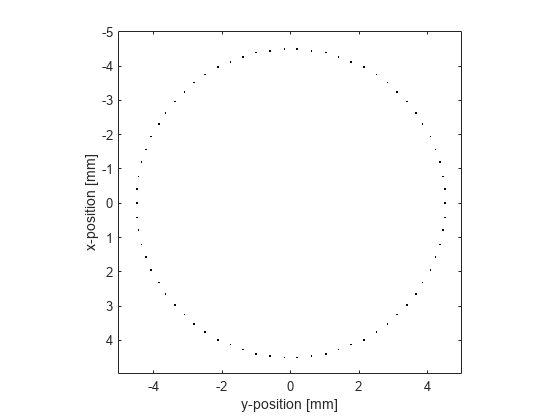

  simulation completed in 8.9196s
  total computation time 10.06s



% assign to the source structure
source.p0 = p0;

% define the properties of the propagation medium
medium.sound_speed = 1500;  % [m/s]

% define a centered Cartesian circular sensor
sensor_radius = 4.5e-3;     % [m]
sensor_angle = 4*pi/2;      % [rad]
sensor_pos = [0, 0];        % [m]
num_sensor_points = 70;
cart_sensor_mask = makeCartCircle(sensor_radius, num_sensor_points, sensor_pos, sensor_angle);

% assign to sensor structure
sensor.mask = cart_sensor_mask;

% create the time array
kgrid.makeTime(medium.sound_speed);

% set the input options
input_args = {'Smooth', false, 'PMLInside', false, 'PlotPML', false};

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});


% add noise to the recorded sensor data
% signal_to_noise_ratio = 40;	% [dB]
% sensor_data = addNoise(sensor_data, signal_to_noise_ratio, 'peak');

二维光声反投影计算脚本 Xu M, Wang LV. Universal back-projection algorithm for photoacoustic computed tomography [published correction appears in Phys Rev E Stat Nonlin Soft Matter Phys. 2007 May;75(5 Pt 2):059903]. Phys Rev E Stat Nonlin Soft Matter Phys. 2005;71(1 Pt 2):016706. doi:10.1103/PhysRevE.71.016706

## 需要的数据

% 传感器记录数据 sensor_data(i,t)
% 模拟网格 Nx,Ny,dx,dy
Nx = kgrid.Nx;Ny = kgrid.Ny;
dx = kgrid.dx;dy = kgrid.dy;

SpeedofSound = 1500; % [m/s]
% 记录时间 t，dt
t = kgrid.t_array; dt = kgrid.dt;

% 传感器位置 r_i 二维数据（实际，标准（以坐标原点为中心））
sensor_location_x = sensor.mask(1,:); % 2*len [x1,y1;x2,y2.....]
sensor_location_y = sensor.mask(2,:);

% 重建图像位置 img_w*h，大小（实际，标准（以坐标原点为中心））
p0_recon1 = zeros(Nx,Ny);
p0_recon_location_x = kgrid.x;
p0_recon_location_y = kgrid.y;

% 每个传感器所占的弧度
arc = 2 * pi * sensor_radius / 70;

% 权重和
 sum_w_omega = 0;

## 论文算法

for i = 1:70
    
    % 计算每个信号到第i个传感器的距离
    distance_x = p0_recon_location_x - sensor_location_x(i);
    distance_y = p0_recon_location_y - sensor_location_y(i);
    distance_xy = sqrt(distance_y.^2 + distance_x.^2);

    % 计算传播需要时间
    distance_xy_time =  distance_xy./SpeedofSound;

    % 计算传播需要步长
    distance_xy_index = floor(distance_xy_time ./dt);
    distance_xy_index(distance_xy_index<1) = 1;

    % 计算权重
    % 公式
    % w_omega = arc/|r-d|^2 * (ns * (r-d)/|r-d|)
    % ns 为指向 信号源侧的 弧长的的单位法向量（单位半径）
    unit_normal_vector = -[sensor_location_x(i),sensor_location_y(i)]./ norm([sensor_location_x(i),sensor_location_y(i)]);
    unit_dp_vector_x = distance_x./distance_xy;
    unit_dp_vector_y = distance_y./distance_xy;
    w_omega = arc ./  distance_xy.^2 .* (unit_dp_vector_x .* sensor_location_x(i) + ...
        unit_dp_vector_y .* sensor_location_y(i)) ./ -norm([sensor_location_x(i),sensor_location_y(i)]);
    
    % 计算返投影项
    % 第i个传感器的信号
    p_i = sensor_data(i,:);

    % 公式
    % b(r,t) = 2*p(r,t) - 2*t*dp(r,t)/d(t)
    % p(r,t) 为 sensor_i 接受到的信号序列
    bp_i = 2*p_i - 2*t .* diff([0,p_i])./dt;
   
    % 加权求和
    p0_i = w_omega .* bp_i(distance_xy_index);
    
    sum_w_omega = sum_w_omega + w_omega;

    p0_recon1 = p0_recon1 + p0_i;
%     break
end
p0_recon12 = p0_recon1 ./sum_w_omega;

## 图

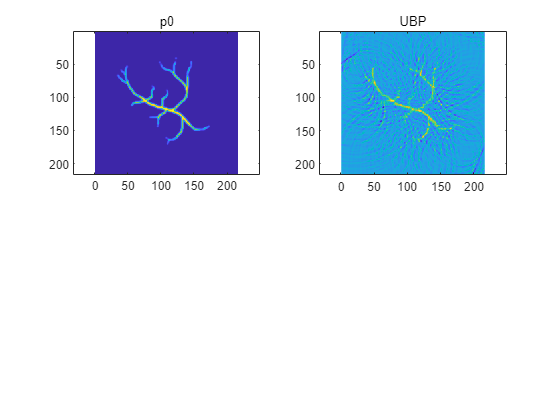

figure,
subplot(221),imagesc(p0),axis equal,title('p0')
subplot(222),imagesc(p0_recon1),axis equal,title('UBP')

create a second computation grid for the reconstruction to avoid the inverse crime

Running k-Wave simulation...
  start time: 04-Apr-2023 22:41:24
  reference sound speed: 1500m/s
  time reversal mode
  dt: 9.2593ns, t_end: 9.4259us, time steps: 1019
  input grid size: 300 by 300 grid points (10 by 10mm)
  maximum supported frequency: 22.5MHz
  expanding computational grid...
  computational grid size: 340 by 340 grid points
           Use dimension sizes with lower prime factors to improve speed
  precomputation completed in 0.37051s
  starting time loop...
  estimated simulation time 11.0351s...


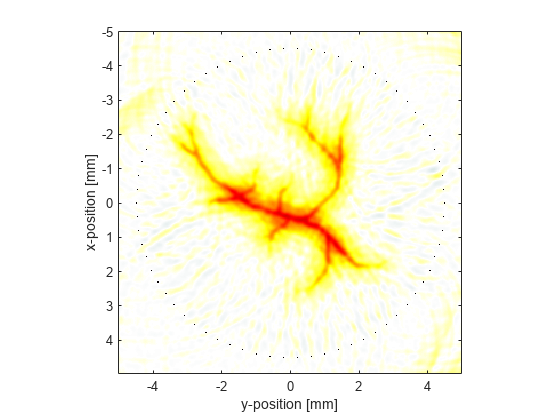

  simulation completed in 11.7466s
  total computation time 12.158s


Nx = 300;           % number of grid points in the x direction
Ny = 300;           % number of grid points in the y direction
dx = x/Nx;          % grid point spacing in the x direction [m]
dy = y/Ny;          % grid point spacing in the y direction [m]
kgrid_recon = kWaveGrid(Nx, dx, Ny, dy);

% use the same time array for the reconstruction
kgrid_recon.setTime(kgrid.Nt, kgrid.dt);

% reset the initial pressure
source.p0 = 0;

% assign the time reversal data
sensor.time_reversal_boundary_data = sensor_data;

% run the time-reversal reconstruction
p0_recon2 = kspaceFirstOrder2D(kgrid_recon, medium, source, sensor, input_args{:});

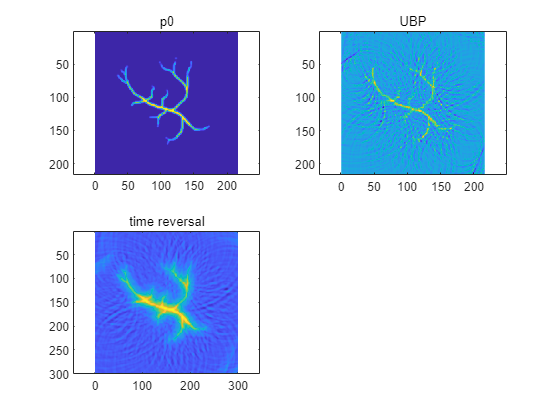


subplot(223),imagesc(p0_recon2),title('time reversal');axis equal

## 插值

create a binary sensor mask of an equivalent continuous circle 

sensor_radius_grid_points = round(sensor_radius / kgrid_recon.dx);
binary_sensor_mask = makeCircle(kgrid_recon.Nx, kgrid_recon.Ny, kgrid_recon.Nx/2 + 1, kgrid_recon.Ny/2 + 1, sensor_radius_grid_points, sensor_angle);

% assign to sensor structure
sensor.mask = binary_sensor_mask;

% interpolate data to remove the gaps and assign to sensor structure
sensor.time_reversal_boundary_data = interpCartData(kgrid_recon, sensor_data, cart_sensor_mask, binary_sensor_mask);

Interpolating Cartesian sensor data...
  interpolation mode: nearest
  number of Cartesian sensor points: 70
  number of binary sensor points: 764
  computation completed in 0.010115s


Running k-Wave simulation...
  start time: 04-Apr-2023 22:41:36
  reference sound speed: 1500m/s
  time reversal mode
  dt: 9.2593ns, t_end: 9.4259us, time steps: 1019
  input grid size: 300 by 300 grid points (10 by 10mm)
  maximum supported frequency: 22.5MHz
  expanding computational grid...
  computational grid size: 340 by 340 grid points
           Use dimension sizes with lower prime factors to improve speed
  precomputation completed in 0.20105s
  starting time loop...
  estimated simulation time 11.4423s...


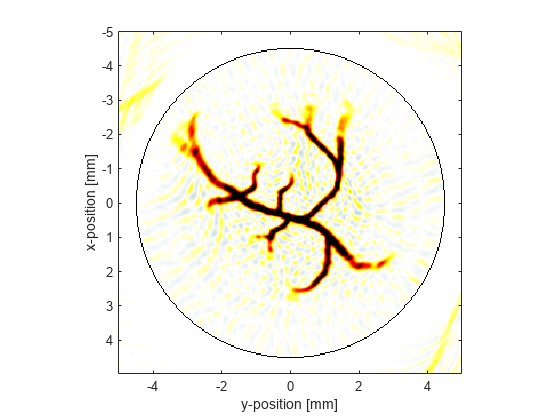

  simulation completed in 11.6497s
  total computation time 11.893s



% run the time-reversal reconstruction
p0_recon_interp = kspaceFirstOrder2D(kgrid_recon, medium, source, sensor, input_args{:});

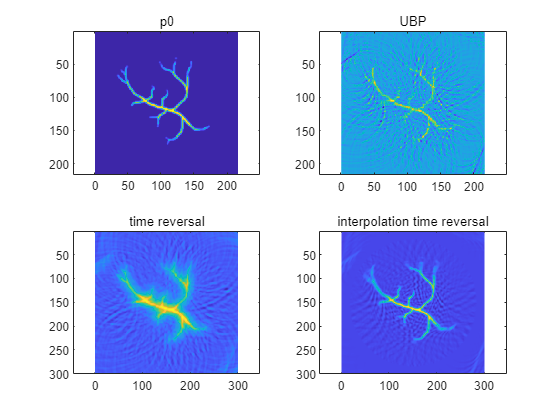

subplot(224),imagesc(p0_recon_interp),title('interpolation time reversal'),axis equal

% % =========================================================================
% % VISUALISATION
% % =========================================================================
% 
% % plot the initial pressure and sensor distribution
% figure;
% imagesc(kgrid.y_vec * 1e3, kgrid.x_vec * 1e3, p0 + cart2grid(kgrid, cart_sensor_mask), [-1, 1]);
% colormap(getColorMap);
% ylabel('x-position [mm]');
% xlabel('y-position [mm]');
% axis image;
% 
% % plot the simulated sensor data
% figure;
% imagesc(sensor_data, [-1, 1]);
% colormap(getColorMap);
% ylabel('Sensor Position');
% xlabel('Time Step');
% colorbar;
% 
% % plot the reconstructed initial pressure 
% figure;
% imagesc(kgrid_recon.y_vec * 1e3, kgrid_recon.x_vec * 1e3, p0_recon, [-1, 1]);
% colormap(getColorMap);
% ylabel('x-position [mm]');
% xlabel('y-position [mm]');
% axis image;
% 
% % plot the reconstructed initial pressure using the interpolated data
% figure;
% imagesc(kgrid_recon.y_vec * 1e3, kgrid_recon.x_vec * 1e3, p0_recon_interp, [-1, 1]);
% colormap(getColorMap);
% ylabel('x-position [mm]');
% xlabel('y-position [mm]');
% axis image;
% 
% % plot a profile for comparison
% slice_pos = 4.5e-3;  % [m] location of the slice from top of grid [m]
% figure;
% plot(kgrid.y_vec * 1e3, p0(round(slice_pos/kgrid.dx), :), 'k--', ...
%      kgrid_recon.y_vec * 1e3, p0_recon(round(slice_pos/kgrid_recon.dx), :), 'r-', ...
%      kgrid_recon.y_vec * 1e3, p0_recon_interp(round(slice_pos/kgrid_recon.dx), :), 'b-');
% xlabel('y-position [mm]');
% ylabel('Pressure');
% legend('Initial Pressure', 'Point Reconstruction', 'Interpolated Reconstruction');
% axis tight;
% set(gca, 'YLim', [0 2.1]);